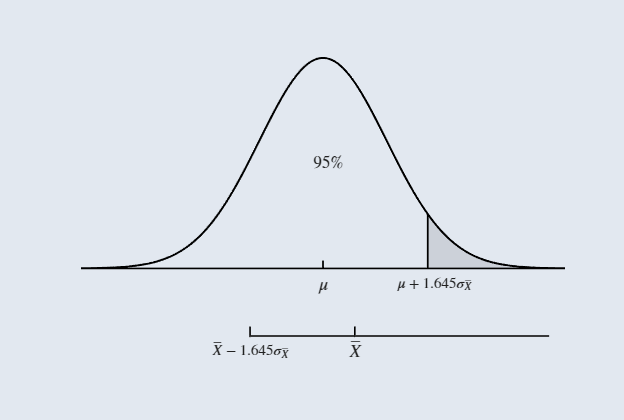

clear
clc

% Parámetros de la distribución normal estándar
mu = 0;
sigma = 1;
x = linspace(-3.8, 3.8, 500);
y = normpdf(x, mu, sigma);

% Color de fondo personalizado
color_fondo = [226 232 240] / 255;

% Configuración de figura y dimensiones
fig = figure('Color', color_fondo);
set(gcf, 'Units', 'inches', 'Position', [0 0 5.2 3.5]);

hold on;

% Parámetros para este gráfico unilateral (1.645 representa el 95% acumulado)
z_crit = 1.645;
y_crit = normpdf(z_crit, mu, sigma);
x_bar = 0.5; % Posición de la media muestral X_bar

% Sombreado de cola derecha únicamente (área superior a 1.645)
x_der = linspace(z_crit, 3.8, 100);
y_der = normpdf(x_der, mu, sigma);
fill([z_crit, x_der, 3.8], [0, y_der, 0], [0.8 0.82 0.85], 'EdgeColor', 'none');

% Curva principal y eje horizontal
plot(x, y, 'k-', 'LineWidth', 1.2);
line([-3.8, 3.8], [0, 0], 'Color', 'k', 'LineWidth', 1);

% Línea vertical en el límite crítico (hasta la curva)
plot([z_crit, z_crit], [0, y_crit], 'k-', 'LineWidth', 1);

% Marcas sobre el eje principal
plot([0, 0], [0, 0.015], 'k-', 'LineWidth', 1);
%plot([x_bar, x_bar], [0, 0.015], 'k-', 'LineWidth', 1);

% Etiquetas matemáticas principales
text(0, -0.03, '$\mu$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 11);
%text(x_bar, -0.03, '$\bar{X}$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 11);
text(z_crit + 0.1, -0.03, '$\mu + 1.645\sigma_{\bar{X}}$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 9);

% Flecha unilateral de área del 95% apuntando a la izquierda
y_arrow = 0.08;
%annotation('arrow', [0.65, 0.32], [0.49, 0.49], 'LineWidth', 0.9);
text((z_crit - 1.5)/2, 2.5*y_arrow, '$95\%$', 'Interpreter', 'latex', ...
    'HorizontalAlignment', 'center', 'BackgroundColor', color_fondo, 'FontSize', 10);

% Intervalo muestral inferior (Eje secundario con flecha hacia la derecha)
y_shift = -0.12;
x_inf_left = x_bar - z_crit; % X_bar - 1.645
x_arrow_end = 3.5;

% Eje horizontal inferior con flecha al final
%annotation('line', [0.42, 0.88], [0.20, 0.20], 'LineWidth', 1);

annotation('line', [0.40, 0.88], [0.20, 0.20], 'LineWidth', 1);

% Marcas del eje inferior
plot([x_inf_left, x_inf_left], [y_shift - 0.01, y_shift + 0.01], 'k-', 'LineWidth', 1);
%plot([0, 0], [y_shift - 0.01, y_shift + 0.01], 'k-', 'LineWidth', 1);
plot([x_bar, x_bar], [y_shift - 0.01, y_shift + 0.01], 'k-', 'LineWidth', 1);

% Etiqueta del límite inferior
text(x_inf_left, y_shift - 0.035, '$\bar{X} - 1.645\sigma_{\bar{X}}$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 9);
text(x_bar, y_shift - 0.035, '$\bar{X}$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 11);


% Formato de ejes
ylim([-0.20, 0.45]);
xlim([-3.8, 3.8]);
axis off;
hold off;

% Exportación idéntica a tu formato
set(gcf, 'Units', 'inches', 'Position', [0 0 5.2 3.5]);
exportgraphics(gcf, 'distribucion_unilateral.png', 'Resolution', 300);
exportgraphics(gcf, 'distribucion_unilateral.svg', 'ContentType', 'vector');